# noise

clear;
Fs = 44100;
T = 1 / Fs;
L = Fs * 1;
% X = zeros(L, 1);
t = (0:L-1)*T;
% size(X)
% mags = zeros(1, L/2+1) + 1;
% mags = randn(1, L/2+1);
mags = linspace(1, 0, L/2 + 1);
mags = sin(220*mags);
mags = mags - min(mags)

mags =     1.0884    1.0785    1.0685    1.0585    1.0486    1.0386    1.0286    1.0187    1.0087    0.9987    0.9887    0.9788    0.9688    0.9588    0.9489    0.9389    0.9289    0.9190    0.9090    0.8991    0.8892    0.8793    0.8694    0.8595    0.8496    0.8398    0.8299    0.8201    0.8103    0.8005    0.7908    0.7810    0.7713    0.7616    0.7519    0.7423    0.7326    0.7230    0.7134    0.7039    0.6944    0.6849    0.6755    0.6660    0.6566    0.6473    0.6380    0.6287    0.6194    0.6102


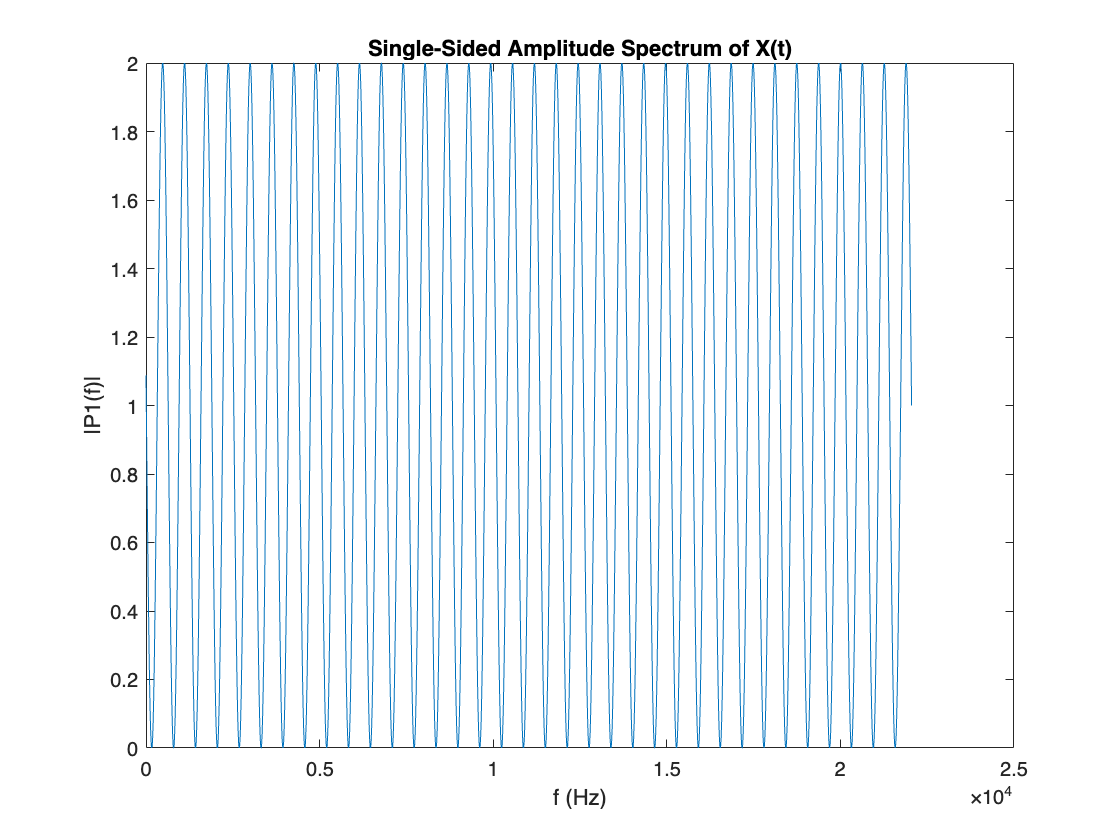

% phases = zeros(1, L/2+1);
% phases = randn(1, L/2+1);
phases = rand(1, L/2+1);
% phases = mod(randn(1, L/2+1), 1);
% phases = linspace(pi, -pi, L/2 + 1);
% phases = tan(phases*20200);
phases = phases - min(phases);
phases = phases / max(phases);
phases = (phases - 0.5) * 2;
phases = phases * pi;

f = Fs/L*(0:(L/2));
plot(f,mags) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

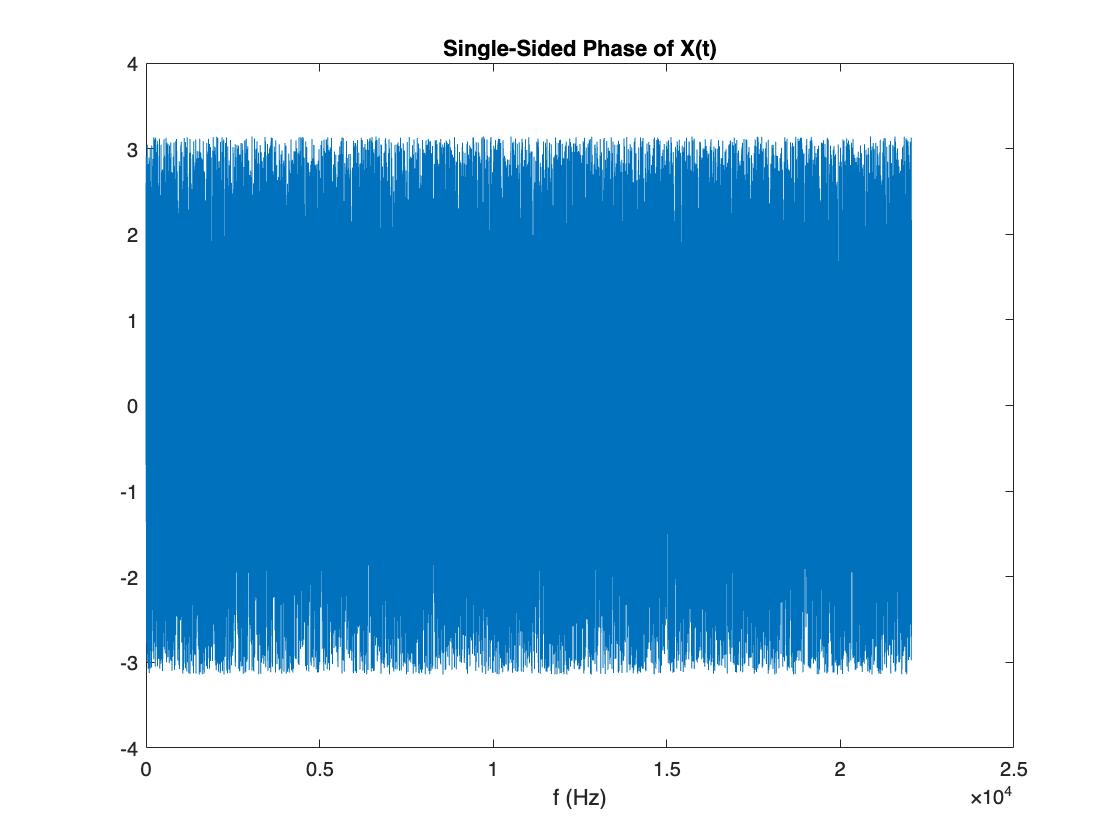

f = Fs/L*(0:(L/2));
plot(f,phases) 
title("Single-Sided Phase of X(t)")
xlabel("f (Hz)")

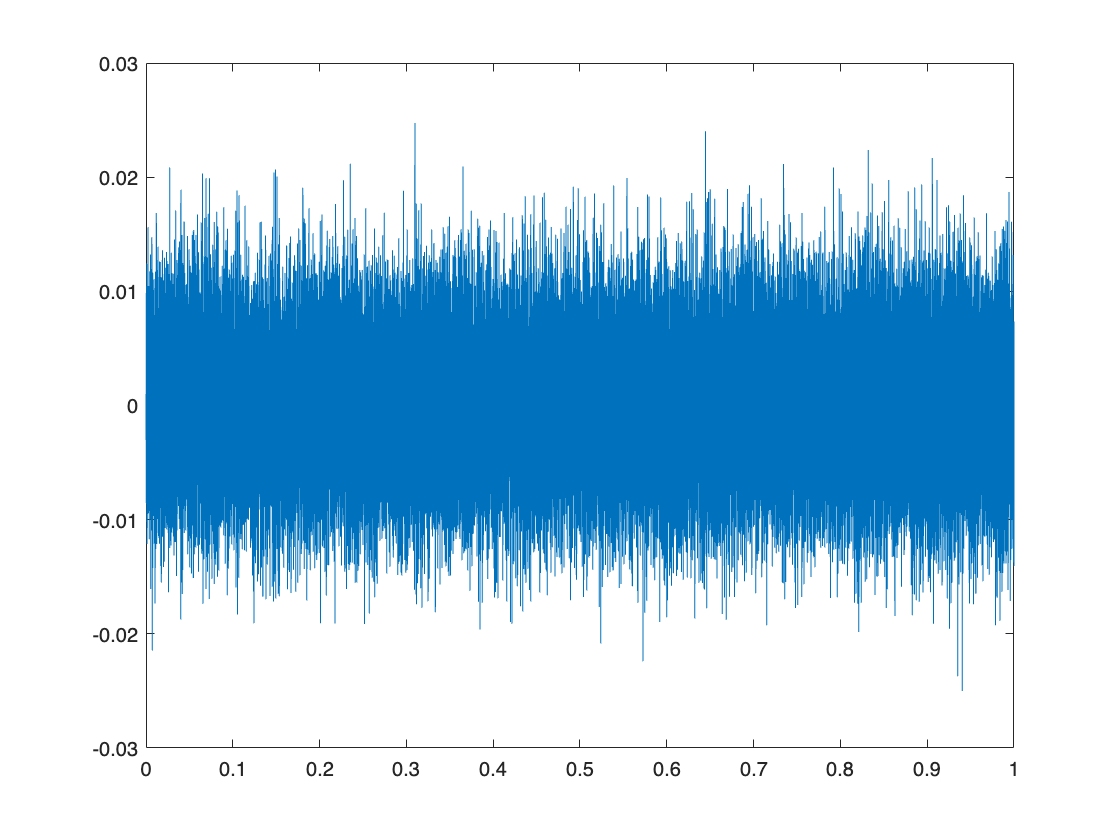


recs = zeros(1, L);
for i = 0:(L/2)
    mag = mags(i+1);
    phase = phases(i+1);
    add = 2*mag/L * cos(2*pi*t*Fs/L*i + 1*phase);
    if i == 0 || i == L/2
        add = add / 2;
    end
    recs = recs + add;
end
plot(t,recs);

recs(1)

ans = 0.0011

recs(end)

ans = 0.0036

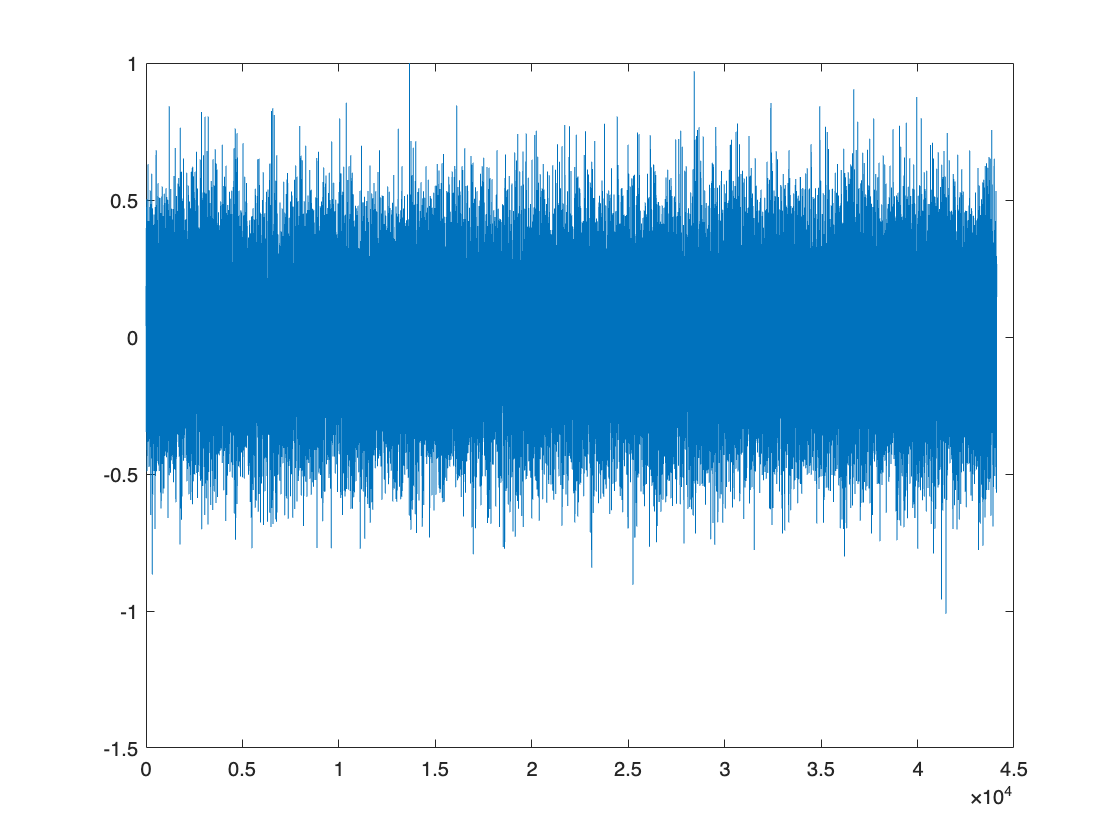

smoothening = 0;

recs = recs(1+smoothening:end-smoothening);
recs = recs / max(recs);
plot((1:L - 2*smoothening),recs);


prepend = linspace(0, recs(1), smoothening)


prepend =

  1×0 empty double row vector



append = linspace(recs(end), 0, smoothening)


append =

  1×0 empty double row vector



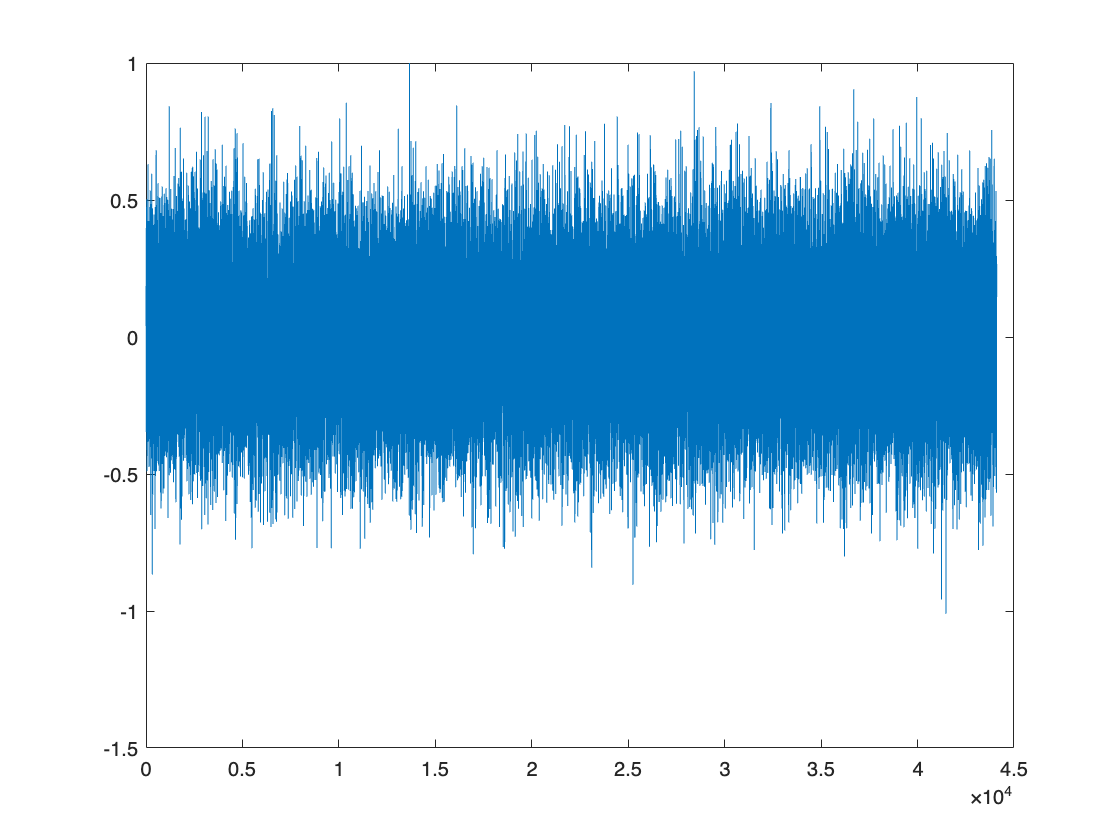

recs = [prepend recs append];
plot((1:L),recs);

recs(1)

ans = 0.0429

recs(end)

ans = 0.1453

min(recs)

ans = -1.0101

max(recs)

ans = 1

audiowrite("recr.wav",recs,Fs)